# Analyzing Re-Alignment

## Recollect all data

load('results_BrainBonus2_Laplace.mat')
recollect_data

## using hilbert transform

test on single subject

t_min = 150;
t_max = 240;
subj_ind = 16;

result = results{subj_ind};
trials = result.trials;
trials = bsxfun(@minus, trials, mean(trials,1));

m = 20;
n = 100;
r = randi(size(trials,3),[n m]);
mask = times > t_min & times < t_max;

resampled_trials = zeros(length(times), 1, n);
for ii = 1:n
    resampled_trials(:,:,ii) = mean(trials(:,:,r(ii,:)),3);
end

[~, mi] = max(resampled_trials.*mask');
[~, m0] = max(mean(trials,3).*mask');
shift = -squeeze(mi-m0);

aligned_trials = align_trials_by_shift(resampled_trials, shift');
aligned_erp = mean(aligned_trials(:,1,:),3);
sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
% sub_aligned_power = get_norm_spectrum_power(sub_trials_aligned, freqs, SamplingInterval./1000, bl_range);
sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);

aligned_power = getPowerSpectra(aligned_trials', SamplingInterval./1000, freqs);
aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);

resampled_power = getPowerSpectra(squeeze(resampled_trials)', SamplingInterval./1000, freqs);
resampled_power = norm_power_bl_range(squeeze(resampled_power), bl_range);

sub_resampled_trials = bsxfun(@minus, squeeze(resampled_trials), squeeze(mean(trials,3)));
sub_power = getPowerSpectra(sub_resampled_trials', SamplingInterval./1000, freqs);
sub_power = norm_power_bl_range(sub_power, bl_range);



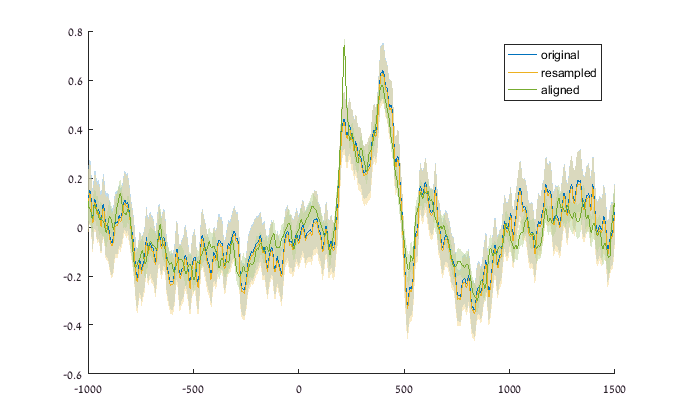

figure;
hold on 
varplot(times, squeeze(trials(:,1,:)))
varplot(times, squeeze(result.trials(:,1,:)))
varplot(times, aligned_trials)
legend({'original', 'resampled','aligned'})

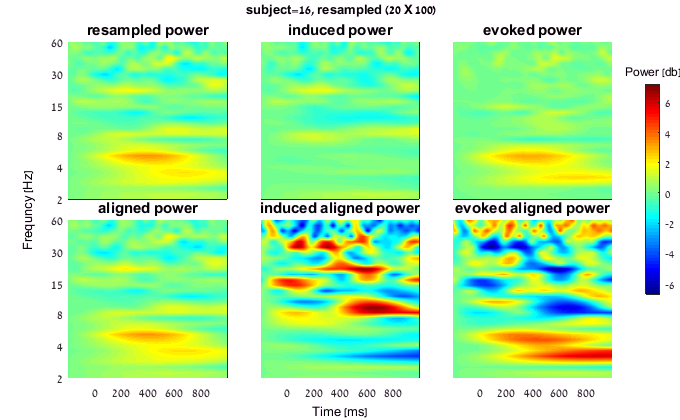

figure;
title_freq = sprintf('subject=%d, resampled (%d X %d)', subj_ind, m, n);
show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(resampled_power(:,u,:),3)), ...
                                squeeze(mean(sub_power(:,u,:),3)), ...
                                squeeze(mean(resampled_power(:,u,:),3))-mean(sub_power(:,u,:),3), ...
                                aligned_power(:,u), ...
                                sub_aligned_power(:,u), ...
                                aligned_power(:,u)-sub_aligned_power(:,u)),...
3, title_freq, 'Power [db]', [], ...
{'resampled power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'}, ...
[], [], [], 0.1)
colormap jet

## Total

Align trials

t_min = 150;
t_max = 250;

power_raw = result.power_raw;

m = 10;
n = 120;
mask = times > t_min & times < t_max;

total_powers_aligned = zeros([length(freqs), length(times), N_subjects]);
sub_powers_aligned = total_powers_aligned;
total_erps_aligned = zeros([ length(times)  N_subjects]);
total_resampled_power = sub_powers_aligned;
total_sub_resampled = total_resampled_power;

for sub_ind = 1:N_subjects
    
    trials = results{sub_ind}.trials;
    trials = bsxfun(@minus, trials, mean(trials,1));
    r = randi(size(trials,3),[n m]);
    resampled_trials = zeros(length(times), 1, n);
    for ii = 1:n
        resampled_trials(:,:,ii) = mean(trials(:,:,r(ii,:)),3);
    end

    [~, mi] = max(resampled_trials.*mask');
    [~, m0] = max(mean(trials,3).*mask');
    shift = -squeeze(mi-m0);
    
    aligned_trials = align_trials_by_shift(resampled_trials, shift');
    aligned_erp = mean(aligned_trials(:,1,:),3);
    sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
    % sub_aligned_power = get_norm_spectrum_power(sub_trials_aligned, freqs, SamplingInterval./1000, bl_range);
    sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
    sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);
    
    aligned_power = getPowerSpectra(aligned_trials', SamplingInterval./1000, freqs);
    aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);
    
    resampled_power = getPowerSpectra(squeeze(resampled_trials)', SamplingInterval./1000, freqs);
    resampled_power = norm_power_bl_range(squeeze(resampled_power), bl_range);
    
    sub_resampled_trials = bsxfun(@minus, squeeze(resampled_trials), squeeze(mean(trials,3)));
    sub_power = getPowerSpectra(sub_resampled_trials', SamplingInterval./1000, freqs);
    sub_power = norm_power_bl_range(sub_power, bl_range);

       
    total_powers_aligned(:,:,sub_ind) = squeeze(aligned_power);        
    sub_powers_aligned  (:,:,sub_ind) = squeeze(sub_aligned_power);
    total_erps_aligned(:,sub_ind) = aligned_erp;
    total_resampled_power(:,:,sub_ind) = squeeze(resampled_power);
    total_sub_resampled(:,:,sub_ind) = squeeze(sub_power);        
end


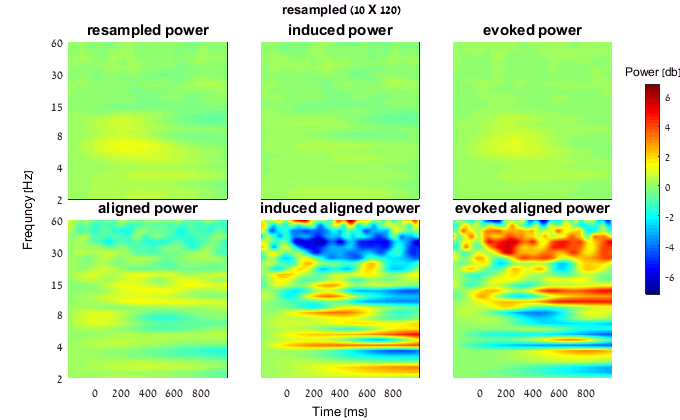

figure;
title_freq = sprintf('resampled (%d X %d)', m, n);
show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(total_resampled_power(:,u,:),3)), ...
                                squeeze(mean(total_sub_resampled(:,u,:),3)), ...
                                squeeze(mean(total_resampled_power(:,u,:),3))-mean(total_sub_resampled(:,u,:),3), ...
                                total_powers_aligned(:,u), ...
                                sub_powers_aligned(:,u), ...
                                total_powers_aligned(:,u)-sub_powers_aligned(:,u)),...
3, title_freq, 'Power [db]', [], ...
{'resampled power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'}, ...
[], [], [], 0.1)
colormap jet

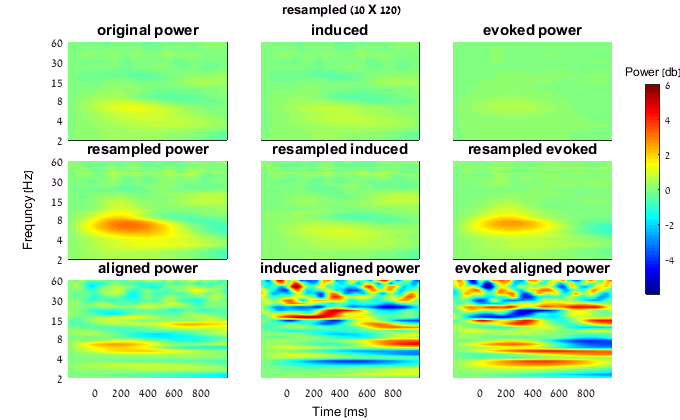

figure;
title_freq = sprintf('resampled (%d X %d)', m, n);

show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(total_powers(:,u,:),3)), ...
                                squeeze(mean(sub_powers(:,u,:),3)), ...
                                squeeze(mean(total_powers(:,u,:),3))-mean(sub_powers(:,u,:),3), ...
                                squeeze(mean(total_resampled_power(:,u,:),3)), ...
                                squeeze(mean(total_sub_resampled(:,u,:),3)), ...
                                squeeze(mean(total_resampled_power(:,u,:),3))-mean(total_sub_resampled(:,u,:),3), ...
                                total_powers_aligned(:,u), ...
                                sub_powers_aligned(:,u), ...
                                total_powers_aligned(:,u)-sub_powers_aligned(:,u)),...
3, title_freq, 'Power [db]', [], ...
{'original power', 'induced', 'evoked power', 'resampled power', 'resampled induced', 'resampled evoked', 'aligned power', 'induced aligned power', 'evoked aligned power'}, ...
[], [], [], 0.1)
colormap jet

## calculate and show different aligned powers

freq_power_240_48 = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 240, 4.5, 8);
freq_power_0_48 = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 0, 4.5, 8);
freq_power__200_48 = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, -200, 4.5, 8);
freq_power_240_1015 = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 240, 10, 15);
freq_power_240_13 = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 240, 1, 3);
freq_power_0_1015 = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 0, 10, 15);


cells2powers = @(powers)reshape(cell2mat(powers),[size(powers{1}), length(powers)]);
t_row = @(t,f1,f2)sprintf('%dms, %.2g-%.2gHz',t,f1,f2);
show_powers = {freq_power_240_48 , 
                freq_power_0_48 ,
                freq_power__200_48 ,
                freq_power_240_1015 ,
                freq_power_240_13 ,
                freq_power_0_1015};
figure;
set(gcf, 'Position', [680    50   795   928])
show_powers_tight(t, freqs, cat(3, ...
                                mean(total_powers(:,u,:),3), ...
                                mean(sub_powers(:,u,:),3), ...
                                mean(total_powers(:,u,:),3)-mean(sub_powers(:,u,:),3), ...
                                cells2powers([show_powers{:}])), ...                                
                    3, 'original vs. several aligned powers', 'Power [db]', [], ...
                    cat(1,'original', cfun(t_row, ...
                    {{240,4.5,8}, 
                    {0,4.5,8},
                    {-200,4.5,8},
                    {240,10,15},
                    {240,1,3},
                    {0,10,15}})), true, ...
                    {'total power', 'induced power', 'evoked power'}, 0.02);
%                     , 'aligned power', 'induced aligned power', 'evoked aligned power'})

colormap jet
min_max = @(X)[min(X(:)) max(X(:))];
set(findobj(gcf,'Type','Axes'), 'CLim', min_max(mean(total_powers(:,u,:),3)));

freq_power_500_48 = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 500, 4.5, 8);

figure;
title_freq = sprintf('@ t=%d ms, f=%.1f-%.1f Hz', t_zero, freq_min, freq_max);
subplot(1,2,1);
varplot(times, squeeze(mean(total_erps,2)))

title({'original trials'})
subplot(1,2,2);
varplot(times, total_erps_aligned)
title({'aligned trials ' title_freq})

figure
show_powers_tight(t, freqs, cat(3, ...
                                mean(total_powers(:,u,:),3), ...
                                mean(sub_powers(:,u,:),3), ...
                                mean(total_powers(:,u,:),3)-mean(sub_powers(:,u,:),3), ...
                                mean(total_powers_aligned(:,u,:),3), ...
                                mean(sub_powers_aligned(:,u,:),3), ...
                                mean(total_powers_aligned(:,u,:),3)-mean(sub_powers_aligned(:,u,:),3)),...
                    3, title_freq, 'Power [db]', [], ...
                    {'total power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'})
colormap jet

## align by ERP

test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 240, 4.5, 8, true)
colormap jet

figure;
show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(total_powers(:,u,:),3)), ...
                                squeeze(mean(sub_powers(:,u,:),3)), ...
                                squeeze(mean(total_powers(:,u,:),3))-squeeze(mean(sub_powers(:,u,:),3)), ...
                                mean(total_powers_aligned(:,u,:),3), ...
                                mean(sub_powers_aligned(:,u,:),3), ...
                                mean(total_powers_aligned(:,u,:),3)-mean(sub_powers_aligned(:,u,:),3)),...
3, title_freq, 'Power [db]', [], ...
{'total power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'})

## Align by cross-correlation (Woody transform)

maxLag = round(100*srate);
shift_func = @(trials) ... 
    cellfun(@(X)-maxLag+output(@()max(xcorr(mean(X,2),X,maxLag)),2), ...
    mat2cell(squeeze(trials)',ones(1,size(trials,3))))';
freq_power_woody = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 100, 0, 0, true, true, shift_func);

## using wavelets

t_zero = 300;
freq_ind = 8:13;
subj_ind = 4;
if isvector(freq_ind)
title_freq = sprintf('@ t = %d ms, f = %.1f-%.1f Hz', t_zero, min(freqs(freq_ind)), max(freqs(freq_ind)));
else
title_freq = sprintf('@ t = %d ms, f = %.1f Hz', t_zero, freqs(freq_ind));
end
result = results{subj_ind };
trials = result.trials;
power = result.original_power;
phases = result.phases;
sub_power = result.sub_power;
% erp = mean(trials(:,1,:),3);
% sub_trials = bsxfun(@minus, trials, erp);
% sub_power = get_norm_spectrum_power(sub_trials, freqs, SamplingInterval./1000, bl_range);
[aligned_trials,shift] = align_by_phase(trials, phases, SamplingInterval, freqs, find(times>t_zero,1), freq_ind);
% aligned_trials = align_trials_by_shift(trials, shift);
aligned_erp = mean(aligned_trials(:,1,:),3);
sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
sub_aligned_power = get_norm_spectrum_power(sub_trials_aligned, freqs, SamplingInterval./1000, bl_range);
aligned_power = align_power_by_shift(power, shift);
ERPfigure;
subplot(1,2,1);
varplot(times, squeeze(trials(:,1,:)))
title({num2str(subj_ind), '(subj) original trials'})
subplot(1,2,2);
varplot(times, squeeze(aligned_trials(:,1,:)))
title({'aligned trials, ' title_freq})
ERPfigure;
subplot(2,3,1);
helperCWTTimeFreqPlot(squeeze(mean(power(:,:,u,:),4)), t, freqs, 'surf', {num2str(subj_ind), '(subj) original power', title_freq})
subplot(2,3,2);
helperCWTTimeFreqPlot(squeeze(mean(sub_power(:,:,u,:),4)), t, freqs, 'surf', {'sub power', title_freq})
subplot(2,3,3);
helperCWTTimeFreqPlot(squeeze(mean(power(:,:,u,:),4))-squeeze(mean(sub_power(:,:,u,:),4)), t, freqs, 'surf', {'evoked power', title_freq})
subplot(2,3,4);
helperCWTTimeFreqPlot(squeeze(mean(aligned_power(:,:,u,:),4)), t, freqs, 'surf', {'aligned power' , title_freq})
subplot(2,3,5);
helperCWTTimeFreqPlot(squeeze(mean(sub_aligned_power(:,:,u,:),4)), t, freqs, 'surf', {'sub aligned power', title_freq})
subplot(2,3,6);
helperCWTTimeFreqPlot(squeeze(mean(aligned_power(:,:,u,:),4))-squeeze(mean(sub_aligned_power(:,:,u,:),4)), t, freqs, 'surf', {'evoked aligned power', title_freq})



function [aligned_powers] = ...
    test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, t0, freq_min, freq_max, align_by_erp, is_shift_func, shift_func)

set_default('is_shift_func', false)
set_default('align_by_erp', false)

t_zero = t0;
N_subjects = length(results);
t=times(u);
total_powers_aligned = zeros([length(freqs), length(times), N_subjects]);

sub_powers_aligned = total_powers_aligned;
total_erps_aligned = zeros([ length(times)  N_subjects]);


for sub_ind = 1:N_subjects
    result = results{sub_ind};
    trials = result.trials;
    power_raw = result.power_raw;

    if ~is_shift_func
        if align_by_erp
            phase_shifts = get_hilbert_phase_shift(mean(trials,3), freq_min, freq_max, SamplingInterval);       
            phase_shifts = repmat(phase_shifts,1,size(trials,3));
        else
            phase_shifts = get_hilbert_phase_shift(trials, freq_min, freq_max, SamplingInterval);
        end    
        shift = phase_shifts(find(times>t_zero,1),:);
    else
        shift = shift_func(trials);
    end

    aligned_trials = align_trials_by_shift(trials, shift);
    aligned_erp = mean(aligned_trials(:,1,:),3);
    aligned_power = align_power_by_shift(power_raw, shift);
    aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);
    
    sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);   
    sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
    sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);
       
    total_powers_aligned(:,:,sub_ind) = squeeze(aligned_power);        
    sub_powers_aligned  (:,:,sub_ind) = squeeze(sub_aligned_power);
    total_erps_aligned(:,sub_ind) = aligned_erp;
        
end

title_freq = sprintf('@ t=%d ms, f=%.1f-%.1f Hz', t_zero, freq_min, freq_max);
if align_by_erp
    title_freq = ['shift by subjects'' ERP' title_freq];
end

figure;
hold on 
varplot(times, squeeze(mean(total_erps,2)))
varplot(times, total_erps_aligned)
title(['ERPs of all trials' title_freq])
legend({'original', 'aligned'})

figure;
show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(total_powers(:,u,:),3)), ...
                                squeeze(mean(sub_powers(:,u,:),3)), ...
                                squeeze(mean(total_powers(:,u,:),3))-squeeze(mean(sub_powers(:,u,:),3)), ...
                                mean(total_powers_aligned(:,u,:),3), ...
                                mean(sub_powers_aligned(:,u,:),3), ...
                                mean(total_powers_aligned(:,u,:),3)-mean(sub_powers_aligned(:,u,:),3)),...
                    3, title_freq, 'Power [db]', [], ...
                    {'total power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'})

colormap jet
min_max = @(X)[min(X(:)) max(X(:))];
set(findobj(gcf,'Type','Axes'), 'CLim', min_max(mean(total_powers(:,u,:),3)));

total_aligned = mean(total_powers_aligned(:,u,:),3);
induced_aligned = mean(sub_powers_aligned(:,u,:),3);
evoked_aligned = mean(total_powers_aligned(:,u,:),3)-mean(sub_powers_aligned(:,u,:),3);

aligned_powers = {total_aligned , induced_aligned , evoked_aligned };

end

function norm_power = norm_power_bl_range(power, bl_range)
    bl_values = mean(mean(power(:, bl_range, :),3),2);
    norm_power = 10 * log10(bsxfun(@rdivide,mean(power,3),bl_values));
end

